%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% alinea (e)
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
q = @(x) -1 + 0.5.*sin(20.*x);
r = @(x) 1 + 30.*(1-x).^2;
l = 0.5;

Fz = @(t, x, y) [y; -q(t).*x + r(t)];
Fw = @(t, x, y) [y; -q(t).*x];

h_vals = [0.2, 0.1, 0.05, 0.025];
max_vals = zeros(1, 4);

figure; hold on;
for idx = 1:4
    h = h_vals(idx);
    [z, ~] = rungekutta(h, 0, 0, Fz, 1);
    [w, ~] = rungekutta(h, 0, 1, Fw, 1);
    s = (l - z(end)) ./ w(end);
    y = z + s.*w;
    x = 0:h:1;
    max_vals(idx) = max(abs(y));
    plot(x, y, 'DisplayName', sprintf('h = %.3f', h));
end

abs(max_vals(3) - max_vals(4))

ans = 1.1567e-04

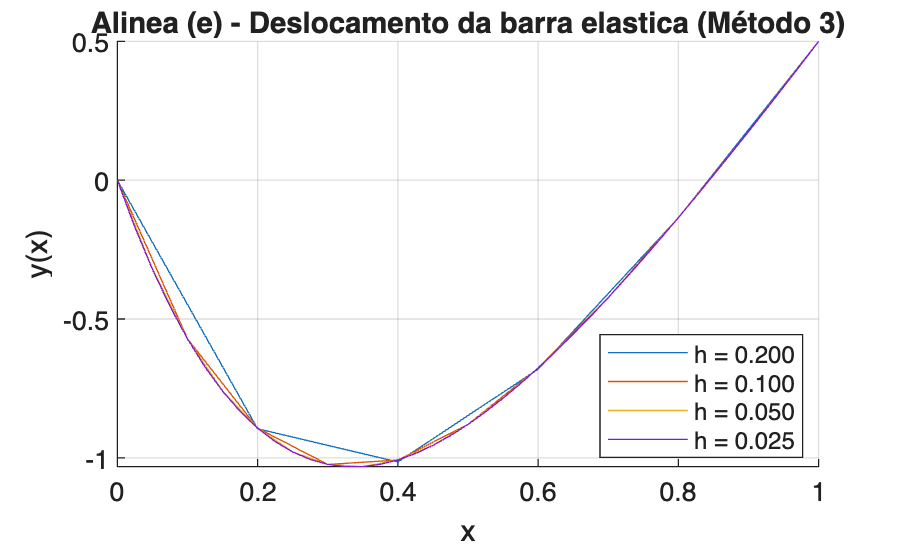

xlabel('x'); ylabel('y(x)');
title('Alinea (e) - Deslocamento da barra elastica (Método 3)');
legend('Location', 'best');
grid on; hold off;


% resultado final com h=0.025
h = 0.025;
[z, ~] = rungekutta(h, 0, 0, Fz, 1);
[w, ~] = rungekutta(h, 0, 1, Fw, 1);
y = z + (l - z(end))./w(end).*w;
x = 0:h:1;
[ymax, idx_max] = max(abs(y));
fprintf('Deslocamento maximo: %f em x = %.4f\n', ymax, x(idx_max));

Deslocamento maximo: 1.031912 em x = 0.3250


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% verificacao
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% método 3 (h=0.025)
x_ref = x; 
y_ref = y;

n_max = 20;
erros1 = zeros(1, n_max + 1);
erros2 = zeros(1, n_max + 1);

for n = 0:n_max
    u1_func = metodo1c(n, q, r, 0, 1, 0, 0.5);
    u2_func = metodo2c(n, q, r, 0, 1, 0, 0.5);
    
    % avaliar método 1 e 2 nos pontos do metodo 3
    y_poli1 = zeros(size(x_ref));
    y_poli2 = zeros(size(x_ref));
    
    for j = 1:length(x_ref)
        y_poli1(j) = u1_func(x_ref(j));
        y_poli2(j) = u2_func(x_ref(j));
    end
    
    % erros
    soma_e1 = 0;
    soma_e2 = 0;
    for j = 1:length(x_ref)
        soma_e1 = soma_e1 + (y_poli1(j) - y_ref(j))^2;
        soma_e2 = soma_e2 + (y_poli2(j) - y_ref(j))^2;
    end
    
    % guardar norma dos erros para cada n
    erros1(n+1) = sqrt(soma_e1 / length(x_ref));
    erros2(n+1) = sqrt(soma_e2 / length(x_ref));
end

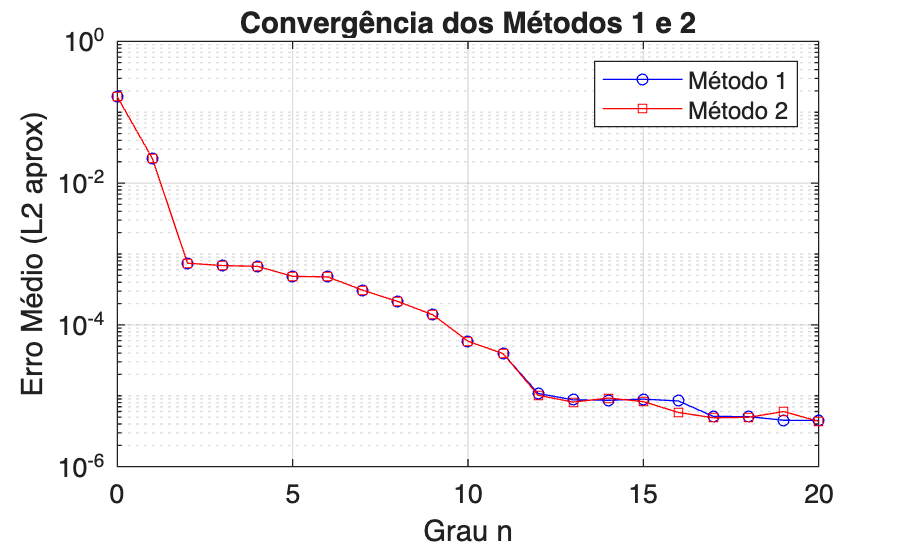


% O erro decresce várias ordens de grandeza com n, por isso usamos escala
% logarítmica no eixo Y. Na escala linear os valores pequenos ficariam
% todos colados a zero e não se via nada
figure;
semilogy(0:n_max, erros1, 'b-o', 'MarkerSize', 4);
hold on;
semilogy(0:n_max, erros2, 'r-s', 'MarkerSize', 4);
grid on;
xlabel('Grau n');
ylabel('Erro Médio (L2 aprox)');
title('Convergência dos Métodos 1 e 2');
legend('Método 1', 'Método 2');
hold off;